# State Feedback and Observer · Lesson

## Execution conditions

MATLAB · Control System Toolbox

## Topics covered

Estimate velocity to control a system that measures only position, and compare estimated velocity and noise sensitivity.

## Two conditions to check before design

Controllability asks whether inputs can move the state; observability asks whether the output's time evolution can distinguish initial states. For a two-state model, compare the ranks of `[B, AB]` and `[C; CA]` with the state count 2.

## Control using unmeasured states

For state feedback $u=-Kx+Nr$, use estimated states when velocity cannot be measured directly. The observer updates its model prediction by adding a measurement-error correction.


$$\dot{\hat x}=A\hat x+Bu+L(y-C\hat x)$$



$$\dot e=(A-LC)e$$


In an ideal linear model, controller and estimator poles can be designed separately. However, with an excessively fast observer, examine how measurement noise propagates to the control input.

## Checking the same design in MATLAB

The observer's state-estimation error is governed by $A-LC$, independently of the input. Place the controller and observer poles separately, then compare actual and estimated states over time.

## Controller and estimator for the same model

Calculate both pole placements and examine estimation-error convergence independently of the input.

%% Worked example
A=[0 1;-2 -3]; B=[0;1]; C=[1 0];
K=place(A,B,[-2 -4]); L=place(A',C',[-8 -10])';
disp(K); disp(L); assert(norm(K-[6 3])<1e-10 && norm(L-[15;33])<1e-10);

     6     3

   15.0000
   33.0000



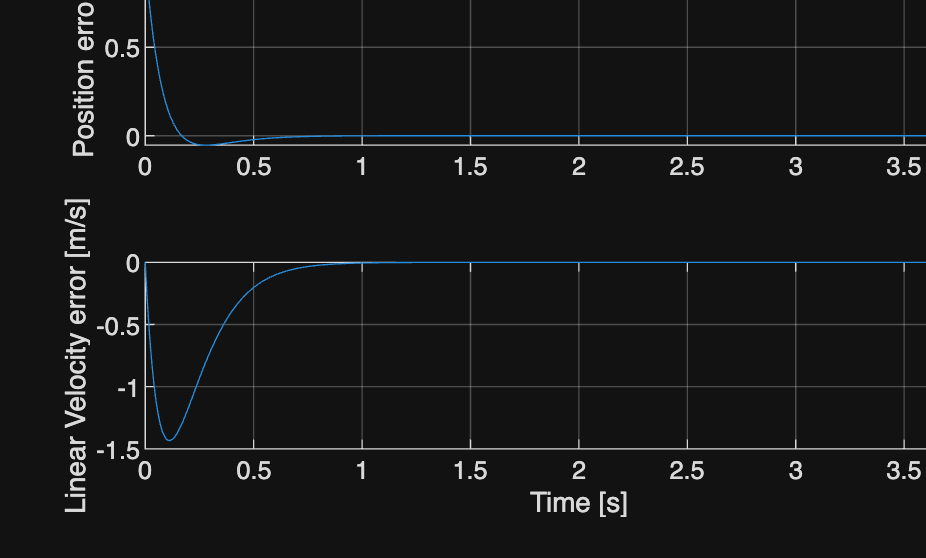

t=linspace(0,4,801)'; estimationError=initial(ss(A-L*C,zeros(2,1),eye(2),zeros(2,1)),[1;0],t);
figure; tiledlayout(2,1);
nexttile; plot(t,estimationError(:,1)); ylabel('Position error [m]'); grid on
nexttile; plot(t,estimationError(:,2)); ylabel('Linear Velocity error [m/s]'); xlabel('Time [s]'); grid on

disp(estimationError(end,:));

   1.0e-12 *

   -0.0316   -0.2215



## Official documentation and data

- [SciPy · Pole placement](https://docs.scipy.org/doc/scipy/reference/generated/scipy.signal.place_poles.html)